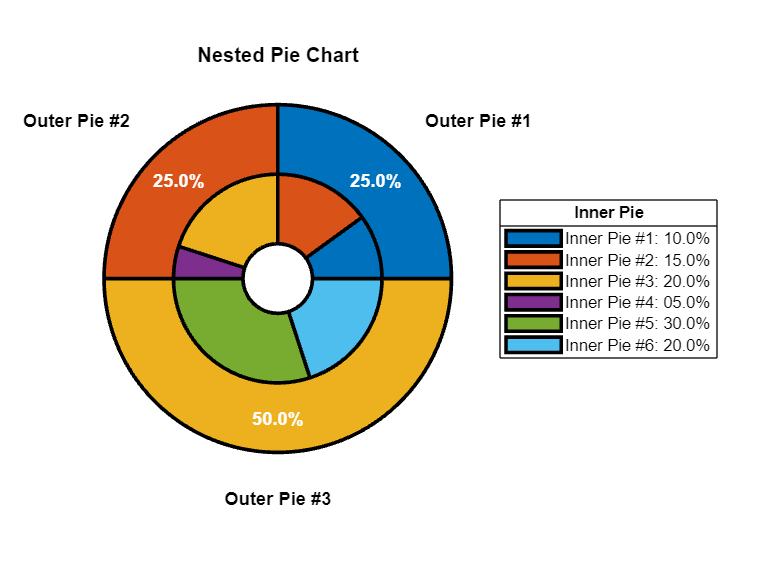

% Example 1: Nested pie chart

% Initialize data points
inner_pie = [0.1, 0.15, 0.2, 0.05, 0.3, 0.2];
outer_pie = [0.25, 0.25, 0.5];
C = {...
    inner_pie,... % Inner pie must come first!
    outer_pie};
outer_label = {...
    'Outer Pie #1',...
    'Outer Pie #2',...
    'Outer Pie #3'};

% Spider plot
pie_nested(C,...
    'PercentStatus', {'off', 'on'},...
    'LabelText', outer_label);

% Title
title('Nested Pie Chart');

% Legend properties
legend_str = cell(length(inner_pie), 1);
for ii = 1:length(legend_str)
    inner_value = inner_pie(ii);
    legend_str{ii} = sprintf('Inner Pie #%i: %04.1f%%', ii, inner_value*100);
end
lg =legend(legend_str, 'Location', 'eastoutside');
lg.Title.String = 'Inner Pie';

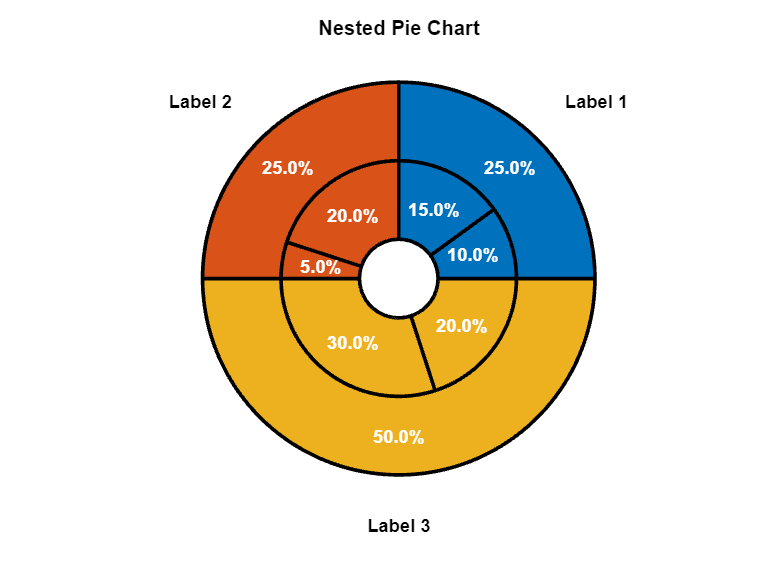

% Example 2: Nested pie chart with custom colors for each wedge

% Initialize data points
inner_pie = [0.1, 0.15, 0.2, 0.05, 0.3, 0.2];
outer_pie = [0.25, 0.25, 0.5];
C = {...
    inner_pie,... % Inner pie must come first!
    outer_pie};

% Custom colors
inner_colors = [...
    0 0.4470 0.7410;...
    0 0.4470 0.7410;...
    0.8500 0.3250 0.0980;...
    0.8500 0.3250 0.0980;...
    0.9290 0.6940 0.1250;...
    0.9290 0.6940 0.1250];
outer_colors = [...
    0 0.4470 0.7410;...
    0.8500 0.3250 0.0980;...
    0.9290 0.6940 0.1250];
wedge_colors = {...
    inner_colors,...
    outer_colors};

% Spider plot
pie_nested(C,...
    'WedgeColors', wedge_colors);

% Title
title('Nested Pie Chart');

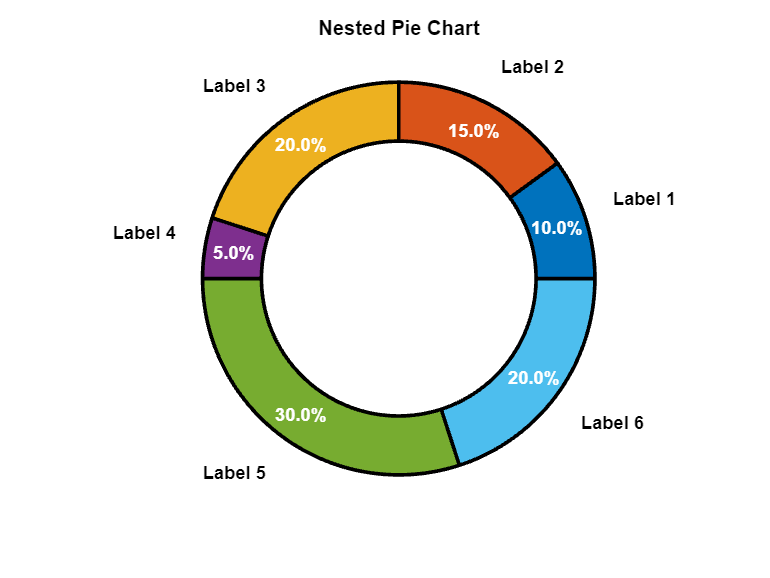

% Example 3: Thin pie chart

% Initialize data points
inner_pie = [0.1, 0.15, 0.2, 0.05, 0.3, 0.2];
C = {inner_pie};

% Spider plot
pie_nested(C,...
    'RhoLower', 0.7);

% Title
title('Nested Pie Chart');

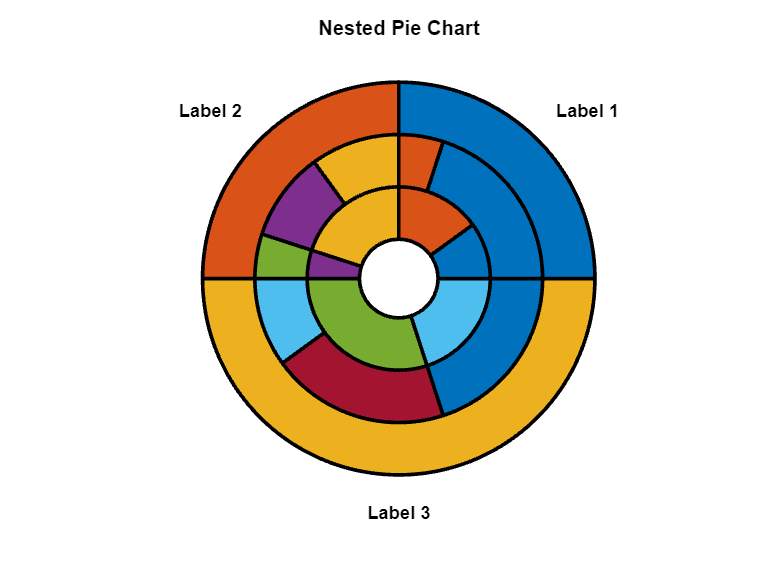

% Example 4: Multi-layer nested pie chart

% Initialize data points
inner_pie = [0.1, 0.15, 0.2, 0.05, 0.3, 0.2];
middle_pie = [0.2, 0.05, 0.1, 0.1, 0.05, 0.1, 0.2, 0.2];
outer_pie = [0.25, 0.25, 0.5];
C = {...
    inner_pie,... % Inner pie must come first!
    middle_pie,...
    outer_pie};

% Spider plot
pie_nested(C,...
    'PercentStatus', {'off', 'off', 'off'});

% Title
title('Nested Pie Chart');